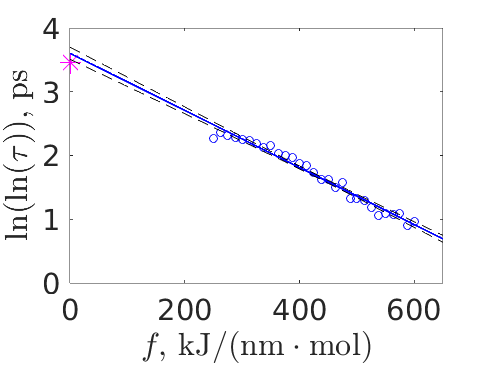

clear;close all;clc;FS=22;
tauexp=50e9*1e3;%ps

ftau=0:5:650;

% load f_tau_with_pbc_atom

tau_with_pbc_atom = [14863.1332292428	40351.1328935425	26435.6432381054	19128.0309490238	12605.7598553897	11544.2573005201	7966.72034483031	4350.22146092382	5452.894858661980	2028.96923794309	1528.69544712381	1358.37407390435	703.876479455918	581.165451266492	290.921292760525	162.231603538146	153.636286405333	90.4647417531491	124.0387635044017	43.8427547446603	42.7468480708459	39.164528587785249	25.7396241034368	17.8855853105338	19.5959255209369	18.8792252890166	19.2214984372752	11.5795130407097	14.0008802389056]';
f = [250 263 275 288 300 313 325 338 350 363 375 388 400 413 425 438 450 463 475 488 500 513 525 538 550 563 575 588 600]';

tau_calc=tau_with_pbc_atom;

[fobj,gof,output]=fit(f,log(log(tau_calc)),'poly1');
ci = confint(fobj,0.68);
pbounds = predint(fobj,ftau,0.68,'functional','on');  % calculates prediction interval (not confidence interval!)
rel_res=(fobj(f)-log(log(tau_calc)))./log(log(tau_calc));

exp(exp(fobj(0)))*1e-12;

% Excluding outliers (points outside of 95% prediction interval)
pbp=predint(fobj,f,0.95,'functional','on');  % 95% prediction interval for f points (not ftau)
ind=find(((log(log(tau_calc)))>pbp(:,1))&((log(log(tau_calc)))<pbp(:,2)));
[fobj_ind,gof,output]=fit(f(ind),log(log(tau_calc(ind))),'poly1');
pbounds_ind = predint(fobj_ind,ftau,0.68,'functional','on');
rel_res_ind=(fobj_ind(f(ind))-log(log(tau_calc(ind))))./log(log(tau_calc(ind)));

exp(exp(fobj_ind(0)))*1e-12;
exp(exp(pbounds_ind(1,:)))*1e-12;

figure
xlim([-5 650])
%subplot(5,1,[1 2 3])

%errorbar(0,log(log(tauexp)),0.07,'.','color','magenta','MarkerSize',12,'LineWidth',4)
plot(0,3.4514,'*','color','magenta','MarkerSize',15)
hold on

plot(f,log(log(tau_calc)),'o','color','blue','LineWidth',0.75)
hold on
xlim([0 650])
pl=plot(fobj);
plot(ftau,pbounds,'--','color','black')
set(pl,'color','blue','LineWidth',1.5)


% ylim([0.5 3.8])
legend off
xlabel('$$f,\,\mathrm{kJ/(nm\cdot mol)}$$','Interpreter','LaTeX')
ylabel('$$\ln(\ln(\tau)),\, \mathrm{ps}$$','Interpreter','LaTeX')
set(gca,'FontSize',FS, 'FontName', 'Times')
hold off

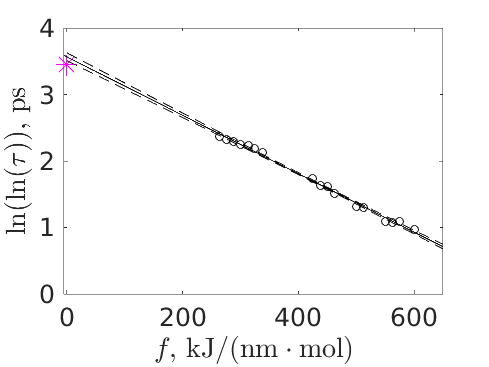


% EXCLUDING OUTLIERS

figure
% axes('Position',[0.6 0.65 0.26 0.26])
% box on
plot(0,3.4514,'*','color','magenta','MarkerSize',15)
hold on
plot(f(ind),log(log(tau_calc(ind))),'o','color','black','LineWidth',0.5)
hold on
xlim([-5 650])
pl_ind=plot(fobj_ind);
plot(ftau,pbounds_ind,'--','color','black','LineWidth',0.25)
set(pl_ind,'color','black','LineWidth',1)
legend off
%ylim([0.8 3.8])
xlabel('$$f,\,\mathrm{kJ/(nm\cdot mol)}$$','Interpreter','LaTeX')
ylabel('$$\ln(\ln(\tau)),\, \mathrm{ps}$$','Interpreter','LaTeX')
set(gca,'FontSize',FS-3, 'FontName', 'Times')

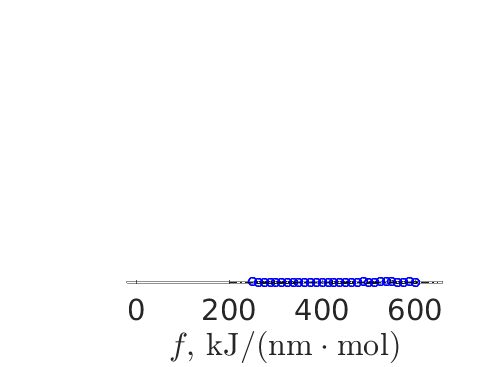

% FROM PAPER FOR JAPANESE CONFERENCE, residuals analysis and q-q plot

subplot(5,1,5)

plot(f,rel_res,'o','color','blue','LineWidth',1.5,'MarkerSize',6)
hold on
plot(f(ind),rel_res(ind),'o','color','black','LineWidth',0.75,'MarkerSize',2.5)
plot([200,650],[0 0],'-.','color','black')
xlim([-20 660])


xlabel('$$f,\,\mathrm{kJ/(nm\cdot mol)}$$','Interpreter','LaTeX')
ylabel('$$\mathrm{Rel.~rez.}$$','Interpreter','LaTeX')
set(gca,'FontSize',FS, 'FontName', 'Times')


set(gcf,'PaperUnits','centimeters','PaperPosition',[0 0 30 20],'PaperSize',[30 20])

print -dpng 'FigFit'

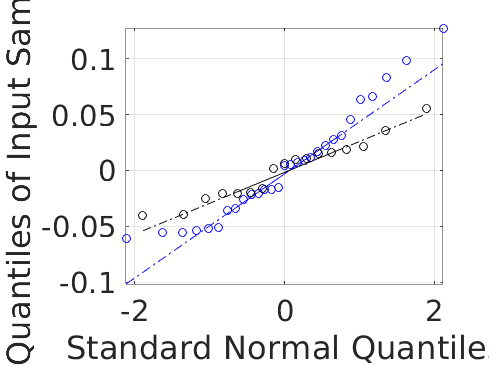


figure
h=qqplot(rel_res);
set(h(1),'Marker','o','MarkerEdgeColor','blue','LineWidth',0.75)
set(h(2),'Marker','none','color','blue','LineWidth',0.75)
set(h(3),'Marker','none','color','blue','LineWidth',0.75)
hold on
%
h_ind=qqplot(rel_res_ind);
set(h_ind(1),'Marker','o','MarkerEdgeColor','black','LineWidth',0.75)
set(h_ind(2),'Marker','none','color','black','LineWidth',0.75)
set(h_ind(3),'Marker','none','color','black','LineWidth',0.75)
grid on
box
title('')
set(gca,'FontSize',FS, 'FontName', 'Times')
set(gcf,'PaperUnits','centimeters','PaperPosition',[0 0 30 15],'PaperSize',[30 15])

print -dpng 'FigQQ'

% EXTRAPOLATED VALUE AND ITS UNCERTAINTY ESTIMATION 

disp('All points')

All points



sigma=(pbounds(1,2)-pbounds(1,1));

Gens=fobj.p2+sigma*randn(1e6,1);   % we sample 10^6 values from a gaussian distribution (we assume that ln(ln(tau)) points are normally distributed) 

TAU=exp(exp(Gens))*1e-12;

tau=median(TAU)   % extrapolated tau(0) in s

tau = 9.2925e+03


% SYMMETRIC MAD
mad_symmetric=median(abs(TAU-tau))

mad_symmetric = 9.2922e+03

tau-mad_symmetric

ans = 0.2775

tau+mad_symmetric

ans = 1.8585e+04

%exp(exp(fobj(0)))*1e-12
%exp(exp(fobj(0)))*1e-12-mad_symmetric
%exp(exp(fobj(0)))*1e-12+mad_symmetric

% ASSYMETRIC MAD

% positive
indp=find(TAU>tau);
TAUp=TAU(indp);
madp=median(abs(TAUp-tau))

madp = 1.3793e+06


%negative
indm=find(TAU<tau);
TAUm=TAU(indm);
madm=median(abs(TAUm-tau))

madm = 9.1799e+03


tau-madm

ans = 112.6372

tau+madp

ans = 1.3886e+06

% exp(exp(fobj(0)))*1e-12-madm
% exp(exp(fobj(0)))*1e-12+madp

disp('Without outliers (outside of 95% confidence interval)')

sigma=(pbounds_ind(1,2)-pbounds_ind(1,1))/2;

Gens=fobj_ind.p2+sigma*randn(1e6,1);

TAU=exp(exp(Gens))*1e-12;

tau=median(TAU)

% SYMMETRIC MAD
mad_symmetric=median(abs(TAU-tau))
tau-mad_symmetric
tau+mad_symmetric
% exp(exp(fobj_ind(0)))*1e-12-mad_symmetric
% exp(exp(fobj_ind(0)))*1e-12+mad_symmetric


% ASSYMETRIC MAD

% positive

indp=find(TAU>tau);
TAUp=TAU(indp);
madp=median(abs(TAUp-tau))

% negative

indm=find(TAU<tau);
TAUm=TAU(indm);
madm=median(abs(TAUm-tau))

tau-madm
tau+madp
% exp(exp(fobj_ind(0)))*1e-12-madm
% exp(exp(fobj_ind(0)))*1e-12+madp